# 実践ロバスト制御　第5章演習問題

clear; close all; clc;

## 問題1

**重み関数のゲインの折れ線図近似が下図になるようにの伝達関数を決めよ。**

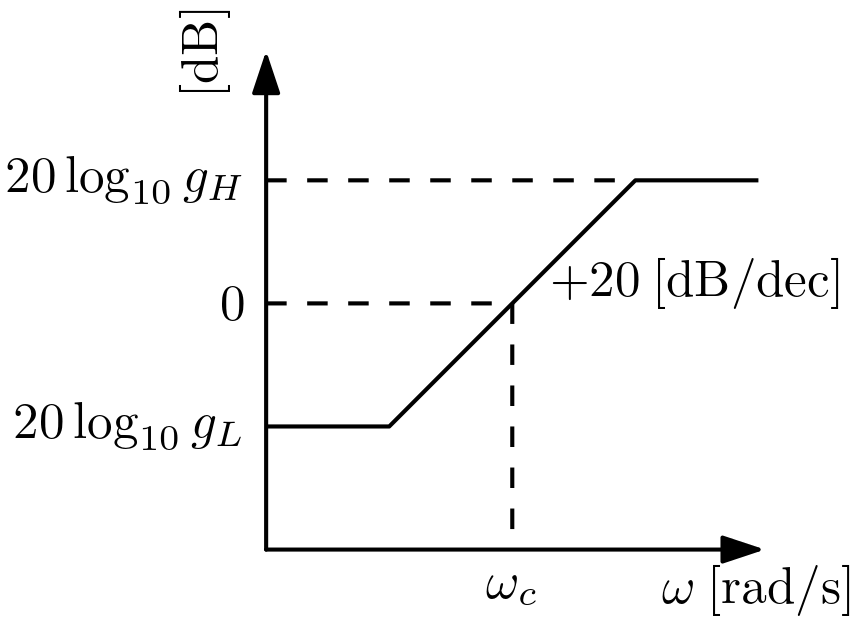


$$W=\frac{s+w_cg_L}{s+w_cg_H}g_H$$


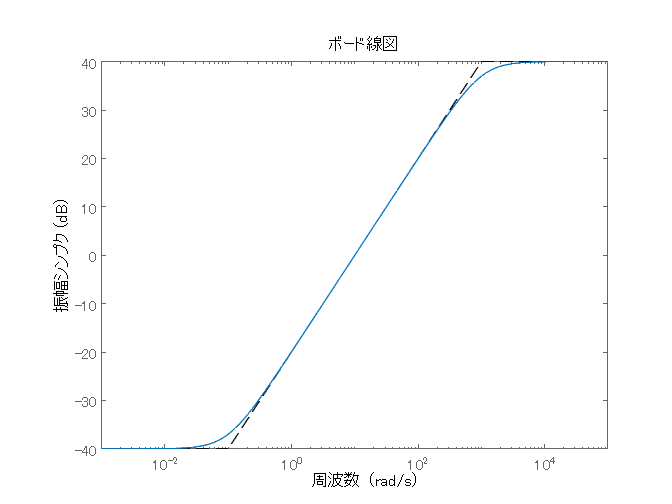

gl = 0.01;
gh = 100;
wc = 10;
w1 = wc*gl/100;
w2 = wc*gh*100;
s = tf("s");
W = gh*(s+wc*gl)/(s+wc*gh);
figure;
plot([w1,wc*gl,wc*gh,w2],[mag2db(gl),mag2db(gl),mag2db(gh),mag2db(gh)],"--","Color","black");hold on;
bodemag(W);

## 問題2

**制御対象を、制御器をとし、これらで構成される直結フィードバック制御系を考える。ただし、およびは1入出力系とし、**$S=1/(1+PK)$**、**$T=PK/(1+PK)$**とする。また、閉ループ系のゲイン余裕を**$g_m$**、位相余裕を**$\phi_m$**とする。このとき、つぎの各問いに答えよ。**

**1. 恒等式のもとで、およびのゲインを同じ周波数で同時に1以上にできることを説明せよ。**

自明。

**2. 感度関数のノルムとの間に次式が成り立つことを示せ。**


$$g_m\ge \frac{1}{1-1/\|S\|_\infty}\text{、}
\phi_m\ge 2 \arcsin
\left(
\frac{1}{2\|S\|_\infty}
\right)$$


**3. 相補感度関数のノルムと、の間に次式が成り立つことを示せ。**


$$g_m\ge 1+\frac{1}{\|T\|_\infty}\text{、}
\phi_m\ge 2 \arcsin
\left(
\frac{1}{2\|T\|_\infty}
\right)$$


2.と3.は$L(j\omega_{180})=-1/g_m$と$\|S\|_\infty\geq S(j\omega_{180})\text{、}
\|T\|_\infty\geq T(j\omega_{180})$を用いて、$|S(j\omega_c)|=1/|-1-L(\omega_c)|=|T(j\omega_c)|=\frac{1}{2\sin(\phi_m/2)}$を用いることで導出できる。

## 問題3

**双一次変換後の状態空間実現が式(5.27)、(5.28)となることを示せ。**


$$x_d[k+1]=A_dx_d[[k]+B_du[k]\\
y[k]=C_dx_d[k]+D_du[k]$$

$$\qquad\text{式(5.27)}\\
\qquad\text{式(5.28)}$$


ただし、$A_d=
\left(I+A_c\frac{T_s}{2}
\right)
\left(I-A_c\frac{T_s}{2}
\right)^{-1}$、$B_d=
\left(I-A_c\frac{T_s}{2}
\right)^{-1}
B_c\sqrt{T_s}$、$C_d=
\sqrt{T_s}C_c
\left(I-A_c\frac{T_s}{2}
\right)^{-1}$、$D_d=D_c+
C_c
\left(I-A_c\frac{T_s}{2}
\right)^{-1}
B_c\frac{T_s}{2}$

連続系の状態空間実現をラプラス変換してから、$s=\frac{2}{T_s}\left(\frac{z-1}{z+1}\right)$を代入し、新たな状態変数$w[k]$を$\sqrt{T}w[k+1]:=
\left(1-\frac{A_cT_s}{2}\right)x[k+1]-\frac{BT}{2}u[k+1]=
\left(1+\frac{A_cT_s}{2}\right)x[k]+\frac{BT}{2}u[k]$と定義して整理することで導出できる。

## 問題4

**得られた制御器が次式に示すように異なる二つの周波数およびにピーク特性を持つとする。ただし、**$0<\zeta_1\ll1$**、**$0<\zeta_2\ll1$**とする。**


$$K=
\underline{
\frac{k_1}{s^2+2\zeta_1\omega_1s+\omega_1^2}
}_{K_1}+
\underline{
\frac{k_2}{s^2+2\zeta_2\omega_2s+\omega_2^2}
}_{K_2}$$


**このとき、これら二つのピーク周波数が変わらないように、双1次変換により離散化を行いたい。どのようにプリワープ処理を行えばよいか考えよ。**

$K_1$を$\omega_1$でプリワープしてから$K_2$を$\omega_2$でプリワープし、両方を足し合わせる。